# **Generating 3D Surface of Ribosome**

Author: Virly Y. Ananda (MATLAB-Dynamo Embedded)

Affiliation: Department of Molecular Biology, Massachusetts General Hospital

Date: June 14, 2023

To obtain 3D surface out of the ribosomes located on the tomogram, template matching table must be generated (angles information included). If you have not done so, refer to template matching scripts before proceeding.

**Step 1: Create a binary mask**

% Read map view of the low-res ribosome.
map1 = dread('ribosomeWT.mrc');
% Invert this map because MATLAB and Chimera reader interpret the map
% differently.
map2 = -map1;
% Convert inverted map to .MRC format.
dwrite(map2,'invertRibosomeWT.mrc');
% Read inverted map
r = dread('invertRibosomeWT.mrc');
% View the inverted map
dview(r);

By this time, Dynamo GUI should pop up and let us visualize the inverted map in X,Y,Z orientations.

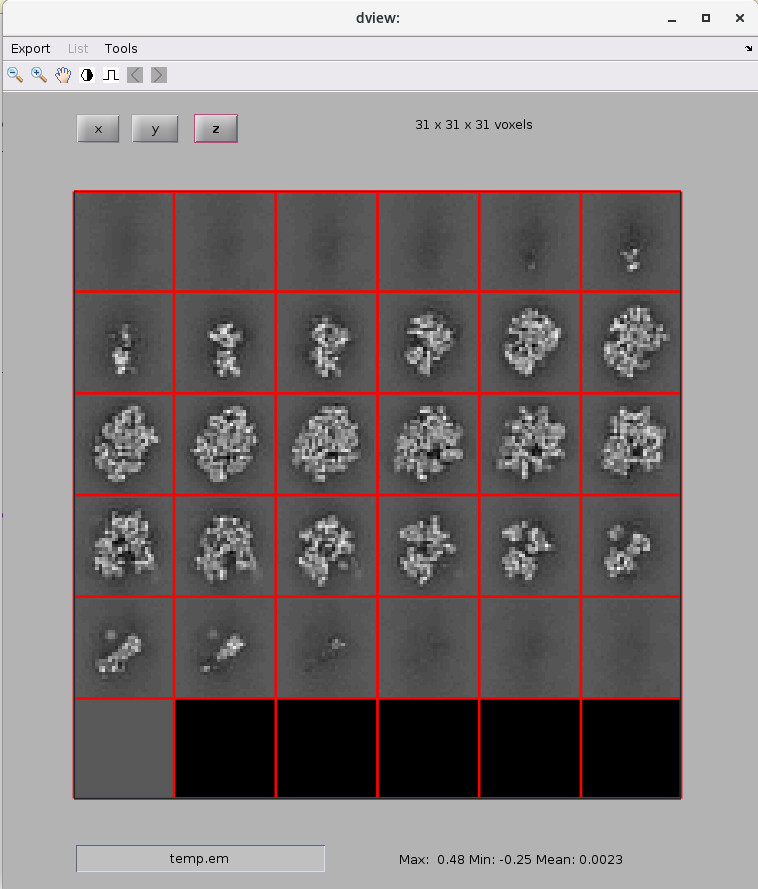

% Perform normalization on ROIs specified by binary mask.
rbright = dynamo_normalize_roi(r);
% Convert the map so it shows black background and white foreground.
mask = zeros(size(rbright));
threshold = -0.1;
% Eliminate densities below it
includedIndices = find(rbright>threshold);
mask(includedIndices) = rbright(includedIndices);
rbright = rbright.*mask;
% Visualize
dview(rbright);

Here we can see that we created a binary mask out of the previous map:

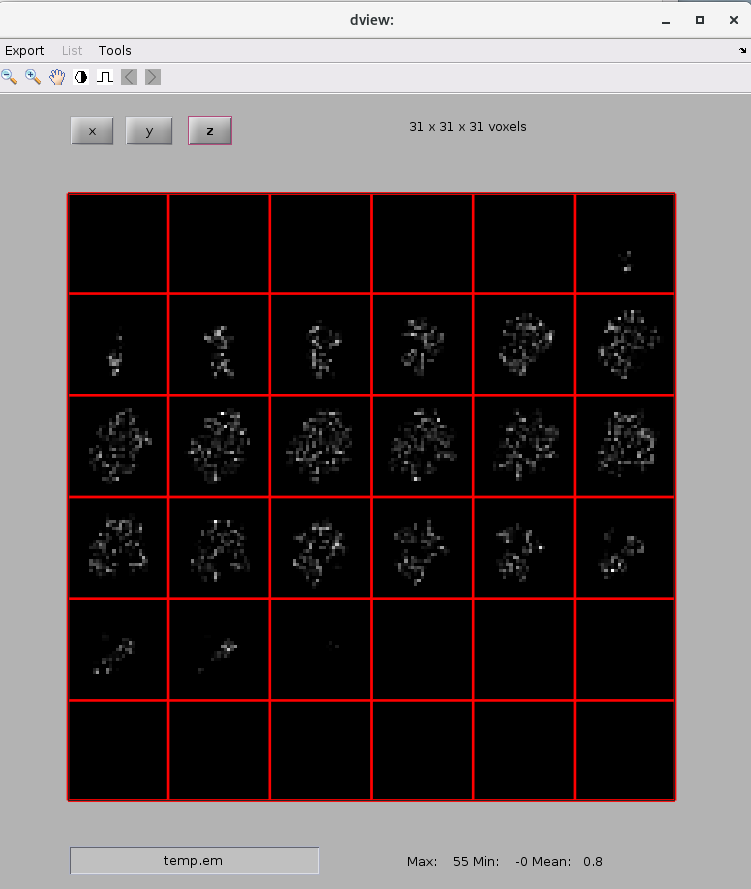

**Step 2: Create a triangulation**

Because triangulation is one of the most necessary step to obtain 3D surface geometrically. We can convert the binary mask into a triangulation object.

% Adjust isolevel
isolevel = 6.2;
% Create isosurface
dt = dynamo_isosurface(rbright.*mask,'isolevel',isolevel,'real_isolevel',true,'-show',false);

% CREATING SURFACE
% Refinement: Create a smoother surface.
tSmoothWT = mbgeom.triangulation.smoothingSubdivision(dt.tr,'mr',1);
% Refinement: Remove any unecessary peaks.
tCleanWT = mbgeom.triangulation.removePeaks(tSmoothWT,'std',2);
% Refinement: Remove any unecessary artifacts.
tNoDustWT=  mbgeom.triangulation.removeDust(tCleanWT);

% Apply surface orientation accordingly so it can be read on any 3D
% software.
tFinalWT = mbgeom.triangulation.consistentNormals(tNoDustWT,'alignTo','out');

 Visualizing our surfaces:

figure; f = gcf; f.Name = 'Construction of WT Ecoli Ribosome Template';

triangulationsToPlot = {dt.tr,tSmoothWT,tCleanWT,tNoDustWT};
titles               = {'Direct Triangulation','Smoothing','Peaks Removed','Dust Removed'};
for i=1:4;
   ax(i) =subplot(2,2,i);
   h(i) = trisurf(triangulationsToPlot{i});
   axis('equal');
   h(i).LineStyle = 'none';
   shading(ax(i), 'interp');
   lightangle(-45,30);
   axis(ax(i),'off');
   ht(i) = title(ax(i),titles{i});
   ht(i).Color = 'w';
   mbgraph.cursors.setMouse3d(ax(i));
end

f.Color = 'k';

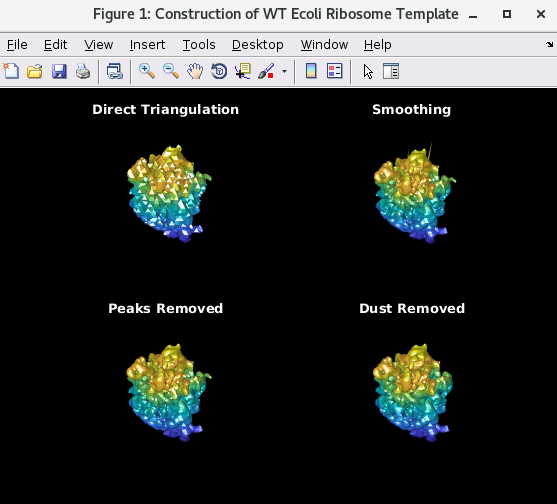

Based on the visualization shown above, we can see the surface adjustment of the ribosome. We can use the surface where dust is removed and apply this to ribosomes detected on the tomogram.

**Step 3: Apply 3D surface on the ribosome localization template**

In our case, it is necessary to distinguish between (discrete) pixel indices and (continuous) point coordinates. We implemented a concrete point using the formula *(N/2+1/2,N/2+1/2,N/2+1/2) where N refers to X,Y,Z voxel size.*

% Apply refined triangulation (3D surface) onto table position
% (WTMaxAngleExcludedTable).

% Since our voxel size is 31x31x31. Simply calculate (31/2)+0.5,(31/2)+0.5,(31/2)+0.5.
tAllWT = dpktbl.triangulation.place(WTMaxAngleExcludedTable,tFinalWT,'rc',16);

**Step 4: Convert 3D surface model to readable format**

Our next step is to generate the 3D surface model and convert it to a readable 3D rendering format (.STL can be viewed in any 3D design software).

% Visualize our model
f=figure; haxis = gca();
%ormaps and graymaps in the same plot
dynamo_colormap();
h = trisurf(tAllWT);
h.LineStyle = 'none';
axis equal;
f.Name = '3D Surfaces of Ribosome on Ecoli WT';
mbgraph.cursors.setMouse3d([]);
shading(haxis, 'interp');
l = lightangle(-45,30);

% Save and conver to .stl file
dynamo_write_stl(tAllWT,'RibosomeEcoliWTMaxV3.stl');


As we can see on the plot shown below, we see 3D surfaces of ribosome based on our tomogram. Color is based on Z stack where yellow indicates the most top view on Z and blue indicates most bottom view on Z stacks.

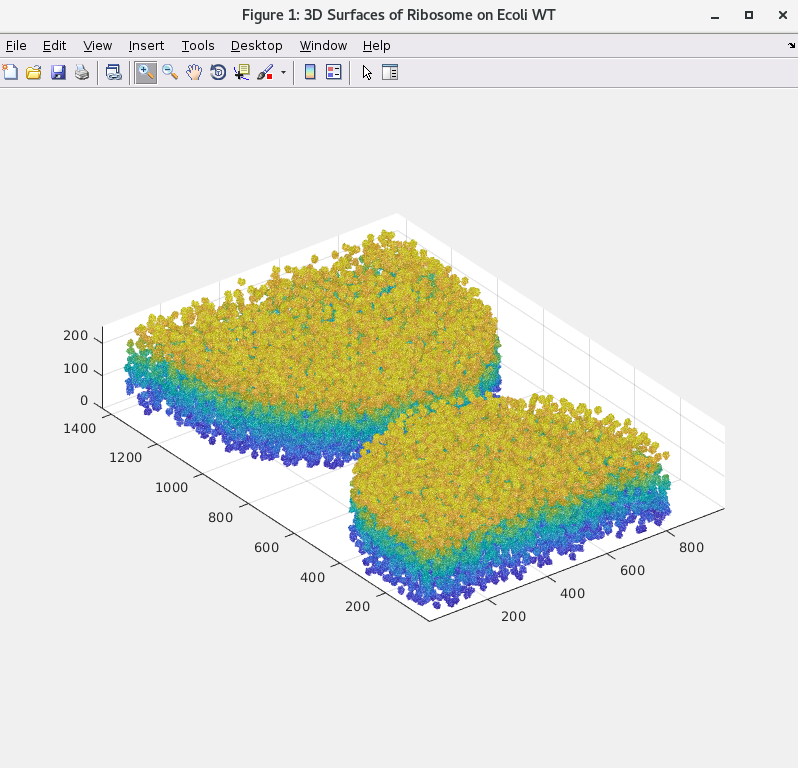

**Step 5: Merging with other 3D surface objects**

- Amira segmentation: Convert to .STL for each label surface.

- On ChimeraX (ArtiaX), load .STL formats of membranes and ribosomes.

- On ChimeraX (ArtiaX), load tomogram used for the template matching/Amira segmentation. Adjust voxel size to 1.